# Cargar información RCAT

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*
clearvars -except study_area;

disp(">>> Declarando variables...ok")

>>> Declarando variables...ok


%directorio de datos
dir_data = "E:\DATA\";
%Priducto MODIS
producto = 'MOD13Q1';
% Área de estudio
archivo_kml = "Naranja_3";

### Obtener la lista de archivos del producto

info_hdf = f_infohdfs2table(dir_data,producto);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1084 archivos


[num_registros_totales,~] = size(info_hdf);

#### Ventana para el mapa region hidrografica rio panuco

% % %Ventana para el mapa region hidrografica rio panuco
[lon_mapa,lat_mapa] = f_get_map_window(dir_data,archivo_kml,0.1);

[coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam,ndvi_tam]...
    = f_get_coordinates(dir_data,archivo_kml,producto,info_hdf,0.20);

>>>>> Obteniendo la zona de estudio
E:\DATA\MOD13Q1\061\*.hdf
>>>>> Analizando 1084 archivos


## Obtener latitud y longitud

if (num_registros_totales > 0)
    % Obtener matrices de latitud y longitud
    [lat,lon,ndvi] = f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## Crear el área de estudio

% crear matriz de 0 y 1 que delimitan el área de estudio
ae = exist("study_area","var");
if ae == 0  %% no existe
    ae = exist("study_area_"+archivo_kml+"_"+producto+".mat","file");
    if ae == 2
        disp(">>> Cargando área de estudio");
        load ("study_area_"+archivo_kml+"_"+producto);

        if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
            disp("La variable area_estudio sera sustituida 1");
            study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
            save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
        else
            disp(">>> Área de estudio existente 1");
        end

    else
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    end
else
    if( numel(study_area) ~= ( ndvi_tam(1)*ndvi_tam(2)) )
        disp("La variable area_estudio sera sustituida 2");
        study_area = f_create_study_area(dir_data+'KML\'+archivo_kml+'.kml',lat,lon);
        save ("study_area_"+archivo_kml+"_"+producto+".mat",'study_area');
    else
        disp(">>> Área de estudio existente 2");
    end
end

>>> Área de estudio existente 2



ndvi = double(ndvi) .* 0.0001;

## Dibujar el mapa

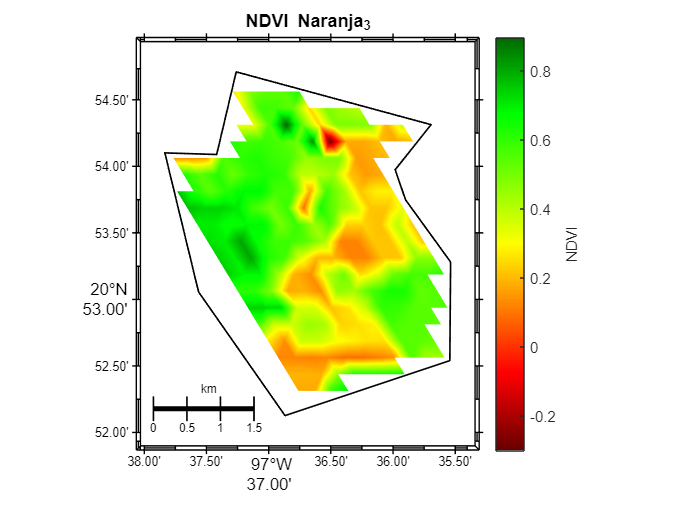

ndvi(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI "+archivo_kml,[],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

disp("a");

a


## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
tmp = find(  info_hdf.anio >= 2000 & info_hdf.anio <= 2022 );
% tmp=find(info_hdf.anio==2022);
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

% arreglo 3d de ndvi por día con filtro Saviztky
arr_ndvi_sgf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d de ndvi por día con filtro Lanczos
arr_ndvi_lf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

#### Leer los datos

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    ndvi(study_area==false)=NaN;
    disponibilidad(study_area==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;
 
    arr_ndvi_lf(:,:,i) = ndvi;
    arr_ndvi_sgf(:,:,i) = ndvi;

    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 


% bp=waitbar(0,'Generando series de tiempo con interpolación'); 
% for i=1:ndvi_tam(1)
%      for j=1:ndvi_tam(2)
%          if study_area(i,j) == true
%             arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));
%             arr_ndvi_com(i,j,:) =  f_fillmissing_linear(arr_ndvi_nan(i,j,:),0);
%          end
% 
%      end
%      waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con interpolación (%3.0f%%) ',(i/ndvi_tam(1)*100)));
% end
% close (bp);

#### Mostrar el promedio de NDVI

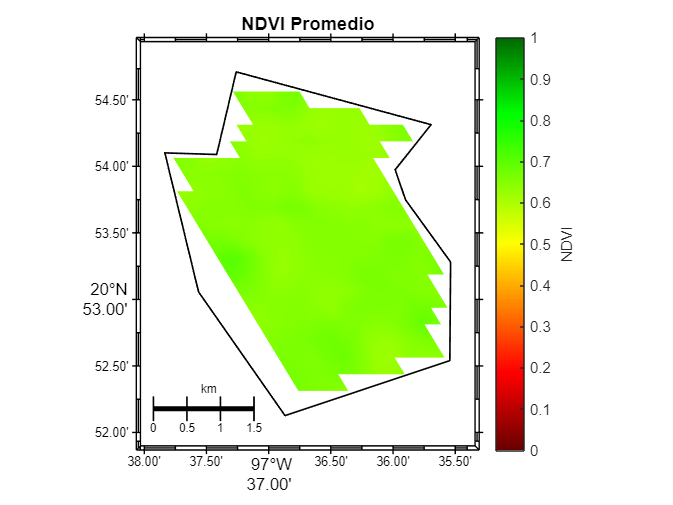

ndvi_prom = f_mean_3dpp(arr_ndvi);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI Promedio",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

## Filtrar con Lanczos y Savitzky-Golay 

%Mejores parametros para el filtro Lanczos
dT = 23;
cf= 1/46;

% Mejores parametros para Savitzky-Golay
order = 3;
framelen = 7;

bp=waitbar(0,'Generando series de tiempo con filtros'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if study_area(i,j) == true

             S  = reshape( arr_ndvi(i,j,:),[],1);
             SNan =  reshape( arr_ndvi_nan(i,j,:),[],1);

             arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));

             [arr_ndvi_nan(i,j,:),~] = f_fillmissing_linear(arr_ndvi_nan(i,j,:),2);

             [xs,~,~,~,~] = lanczosfilter(S,dT,cf,[],'low');  
             arr_ndvi_lf(i,j,:) = xs;

             arr_ndvi_sgf(i,j,:) = sgolayfilt(S,order,framelen);

         end

     end
     waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con filtros (%3.0f%%) ',(i/ndvi_tam(1)*100)));
end
close (bp);

#### Mostrar el promedio de NDVI FILTRO LANCZOS de toda la serie

ndvi_prom = f_mean_3dpp(arr_ndvi_lf);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI LF",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

% exportgraphics(gca,"img/promedio_ndvi_lf.png",'Resolution',300) 



#### Mostrar el promedio de NDVI FILTRO SAVITZKY de toda la serie

ndvi_prom = f_mean_3dpp(arr_ndvi_sgf);
ndvi_prom(study_area==false)=nan;

figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI SGF",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,archivo_kml,1,'k');

% exportgraphics(gca,"img/RCAT01_promedio.png",'Resolution',300) 


## Serie de tiempo

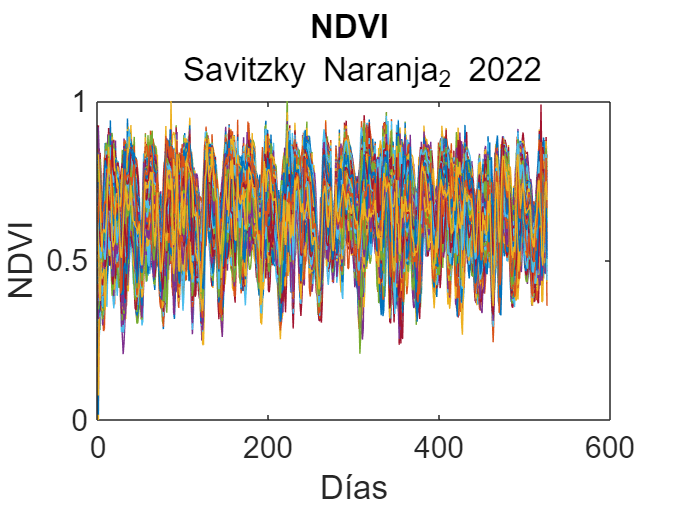

figure;
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
        if(study_area(i,j)==1)

            serie = reshape(arr_ndvi_sgf(i,j,:),[],1);
            plot(serie)
            hold on
        end
    end
end
hold off

%title('NDVI promedio x estación');
xlabel('Días','FontSize',18);
% xticks(1:length(linea_tiempo_promedio));
% xticklabels(lbl_ejex);
ylabel('NDVI','FontSize',18);
% xlim([0 (length(linea_tiempo_promedio)+1)]);
ylim([0 1]);
% xtickangle(45);
ax = gca;
ax.FontSize=18; 
title("NDVI "," Savitzky "+archivo_kml+" "+2022)

% title("NDVI ",""+archivo_kml+" "+2022)
% exportgraphics(gca,"img/RCAT01_grafica.png",'Resolution',300);


Graficado por pixel en un año

% 
% figure
% hold on
% 
% serie_px_sv = reshape(arr_ndvi_sgf(10,10,:),[],1);
% serie_px_n = reshape(arr_ndvi(10,10,:),[],1);
% 
% plot(serie_px_sv);
% plot(serie_px_n);
% 
% ylabel("NDVI");
% xlabel("Mes")
% legend("Savitzky","NDVI","Location","south")
% ylim=[0 1];
% hold off
% 



Promedio por mes NDVI al año

% s



Promedio diario en un año

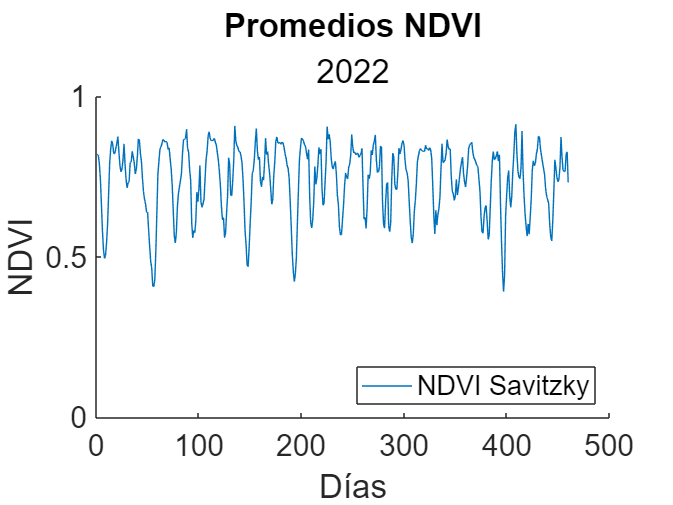

% indx=find(info_hdf.anio==2022);

indx=find(info_hdf.anio>=2003 & info_hdf.anio<=2022 );
arr_ndvi_temp=arr_ndvi_sgf(:,:,indx);  
[~,~,sr]=size(arr_ndvi_temp);

for i=1:sr
    p_mes_ndvi_m1(i)=mean(arr_ndvi_temp(:,:,i),"all","omitnan");
    p_mes_ndvi_sv_m1(i)=mean(arr_ndvi_temp(:,:,i),"all","omitnan");
end

figure
hold on
% plot(p_mes_ndvi_m1);


plot( p_mes_ndvi_sv_m1);
ylim([0 1]);
ax = gca;
ax.FontSize=18; 
xlabel("Días")
ylabel("NDVI")

hold off
title("Promedios NDVI","2022")
legend("NDVI Savitzky","Location","southeast")

Promedio Por año NDVI

figure
init= 2003 %info_hdf.anio(1)

init = 2003

finish= 2022 %info_hdf.anio(size(info_hdf,1))

finish = 2022

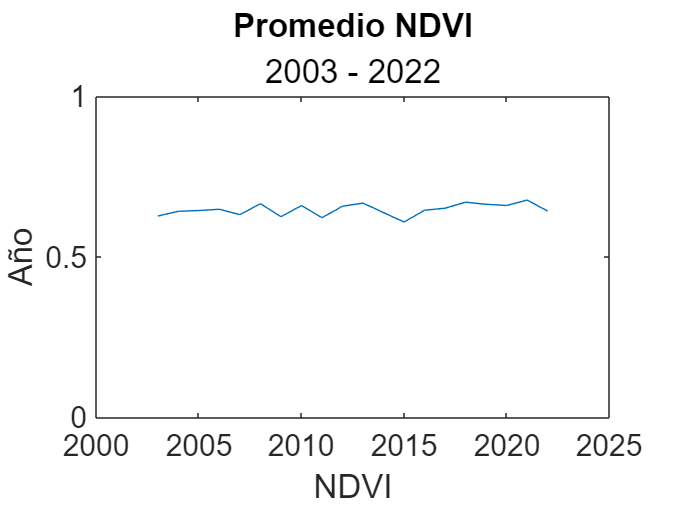

% mes=[];
% ps_1=[];
eage_temp_sv=[];
mean_eage_sv=[];
pivot=1;
eage_x=[];
for i=init:finish
    eage_temp_sv{pivot}=find(info_hdf.anio==i);
    mean_eage_sv(pivot)=mean(arr_ndvi_sgf(:,:,eage_temp_sv{pivot}),"all","omitnan");
    eage_x(1,pivot)=i;
    pivot=pivot+1;
end

% Graficando promerio por año 
plot(eage_x,mean_eage_sv);
title('Promedio NDVI','2003 - 2022')
xlabel("NDVI")
ylabel("Año")
ylim([0 1]);
ax = gca;
ax.FontSize=18; 
hold off

Comparacion de datos dia

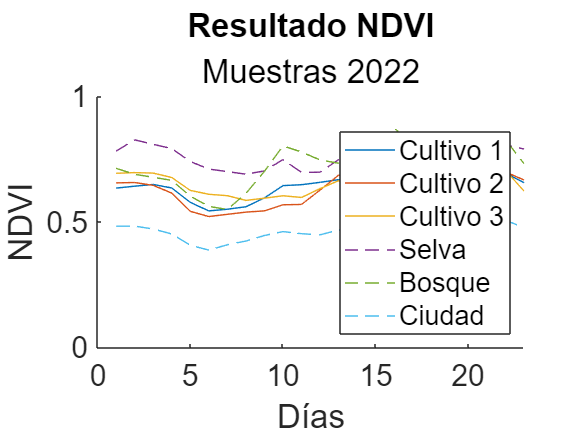

figure
hold on
ax = gca;
ax.FontSize=18; 

plot(p_cultiv_1_d_22);
plot(p_cultiv_2_d_22);
plot(p_cultiv_3_d_22);
plot(p_selva_d_22,'--' );
plot(p_bosque_d_22,'--');
plot(p_ciudad_d_22,'--')


xlabel("Días")
ylabel("NDVI")
title("Resultado NDVI","Muestras 2022")
ylim([0 1])

legend("Cultivo 1","Cultivo 2","Cultivo 3","Selva","Bosque","Ciudad" ,"Location","southeast")
hold off

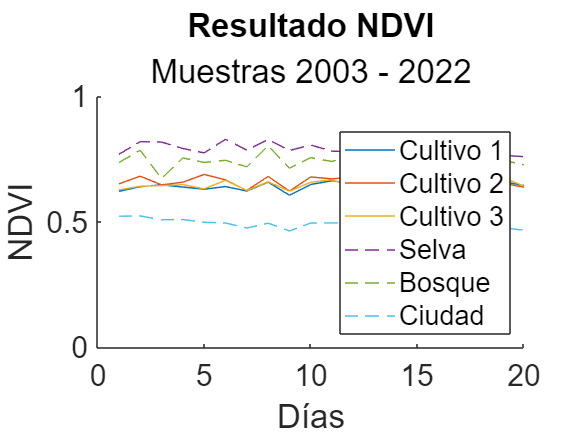

figure
hold on
ax = gca;
ax.FontSize=18; 

plot(p_cultiv_1_a_03_22);
plot(p_cultiv_2_a_03_22);
plot(p_cultiv_3_a_03_22);
plot(p_selva_a_03_22,'--' );
plot(p_bosque_a_03_22,'--');
plot(p_ciudad_a_03_22,'--')


xlabel("Días")
ylabel("NDVI")
title("Resultado NDVI","Muestras 2003 - 2022")
ylim([0 1])

legend("Cultivo 1","Cultivo 2","Cultivo 3","Selva","Bosque","Ciudad" ,"Location","southeast")
hold off